% Parameters
tf = 6;
ts = 1;
tmid = 3;
sigma = 0.1;
freq = 100.6;
Nt = 100000;

[t, y1] = sound1(tf, Nt, ts, sigma, freq);


freq = 120

freq = 120

ts =2;
[t, y2] = sound1(tf, Nt, ts, sigma, freq);


freq = 150

freq = 150

ts = 0.5;
[t, y3] = sound1(tf, Nt, ts, sigma, freq);


y1 = y1./max(y1);
y2 = y2./max(y2);
y3 = y3./max(y3);


y = y1 + y2+ y3/3

y =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000


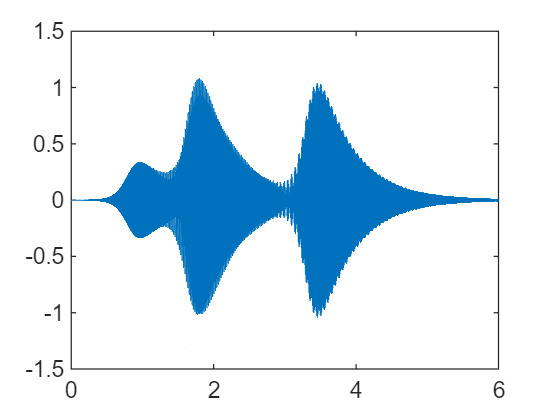


Fs = round(Nt/tf);
plot(t,y)

soundsc(y,Fs,[-3,3])

Fs44 = 44.1e3;
y44 = resample(y,Fs44,Fs)/5

y44 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



audiowrite("SynthesizedSound.mp4",y44,Fs44)

function [t, y1] = sound1(tf, Nt, ts, sigma, freq)
% Domain and function
ylims = [-1,1];
tlims = [0,tf];
freqLims = [-4,4];
t = linspace(tlims(1),tlims(2),Nt);
sechValue = 2./(exp((0.2*t-ts)/sigma) + exp(-(t-ts)/sigma));
y1 = sin(2*pi*freq*t).*sechValue/1200;
end